%%----------------------------------------------------%%
%%----- Vahid Jamali
%%----- IRS-Assisted Wireless Communications
%%----------------------------------------------------%%

%close all
clear all
% clc
Cluster = 0;

addpath('./IRS_coeffs_functions')

#### Initialization:

f = 60e9; % frequency
c = physconst('lightspeed'); % speed of light
lambda = c/f; % wavelength

Qy=160;
Qz=160;

dy = lambda/2; % element spacing
dz = lambda/2; % element spacing

Ly = Qy*dy; % IRS dimension
Lz =Qz*dz; % IRS dimension


p_AP = [2 0 2]; % BS position
p_IRS = [0 2 3]; % IRS position
p_focus = [2 2 3]; % center point; the MU and the IRS are both oriented along the perpendicular to the IRS surface, which is perpendicular to the yz plane

N = 1e2; % number of points for grid discretization


Dp_y_tot = [1.5]; % Wide beam parameter

Dp_z_tot = Dp_y_tot; % Wide beam parameter

Dobs = 7; % A D*D square observation area
gtilde = 4*pi*dy*dz/(lambda^2); % unit-less unit-cell factor

#### Transmit power and noise variance:

Ptx_dBm = 30; % transmit power in dBm
Ptx = db2pow(Ptx_dBm-30);

N0 = -174;  % dBm/Hz
bandwidth = 2640e6; % MHz [1, first table]
Nf = 6;  % noise figure dB
var_noise = bandwidth*db2pow(N0-30)*db2pow(Nf)

var_noise = 4.1841e-11


NoiseFloor = -89.9;    % STA noise floor in dBm
var_noise=db2pow(NoiseFloor-30)

var_noise = 1.0233e-12

#### Operating regime:

D = sqrt(Ly^2+Lz^2);
dnear = sqrt(8*D^3/lambda)

dnear = 17.0068

dfar = 2*D^2/lambda

dfar = 127.9114


p_center = p_focus;
d1 = norm(p_AP-p_IRS)

d1 = 3

d2 = norm(p_center-p_IRS)

d2 = 2

#### For loop:

for ii = 1:length(Dp_y_tot)

    Dp_y = Dp_y_tot(ii);
    Dp_z = Dp_z_tot(ii);

#### Wide beam

    Param_phase = struct('Ly',Ly,'Lz',Lz,'dy',dy,'dz',dz,'Qy',Qy,'Qz',Qz, ...
        'p_IRS',p_IRS,'p_BS',p_AP,'p_focus',p_focus,...
        'Dp_y',Dp_y,'Dp_z',Dp_z,'lambda',lambda);
    [IRS_phase] =  func_phase_near(Param_phase); % IRS phase shifts

    grid_point = (linspace(-Dobs/2,Dobs/2,N))';

    for mm = 1:N

        p_obs = ones(N,1)*p_center + [zeros(N,1) grid_point grid_point(mm)*ones(N,1)]; % observation points

        Param_g = struct('Ly',Ly,'Lz',Lz,'dy',dy,'dz',dz,'lambda',lambda,'Qy',Qy,'Qz',Qz, ...
            'p_IRS',p_IRS,'p_BS',p_AP,'p_obs',p_obs,...
            'IRS_phase',IRS_phase);
        [g_irs(mm,:)] = func_g_IRS_near(Param_g);

        PLi = (lambda/(2*pi*norm(p_IRS-p_AP)))^2;
        PLr = (lambda/(2*pi*norm(p_focus-p_IRS)))^2;
        [SNR(mm,:)] = Ptx*(abs(g_irs(mm,:))).^2*PLi*PLr/var_noise;
    end


    g_irs_dB(:,:,ii) = 20*log10(abs(g_irs));

    g_max = Qy*Qz*gtilde;
    g_max_dB = 20*log10(abs(g_max));

    g_irs_dB_norm(:,:,ii) = g_irs_dB(:,:,ii)-g_max;

    SNR_dB(:,:,ii) = pow2db(SNR);

end

#### Plotting the SNR in dB

close all;
fontsize=15;
y_points = p_center(2)+grid_point;
z_points = p_center(3)+grid_point;
[Y,Z]=meshgrid(y_points,z_points);

[M,c]=contourf(Y,Z,SNR_dB(:,:,1),"ShowText",true); hold on;
colorbar
c.LabelFormat="%0.0f dB"

c =   Contour with properties:

    EdgeColor: [0 0 0]
    LineStyle: '-'
    LineWidth: 0.5000
    FaceColor: 'flat'
    LevelList: [3.2157 5 10 15 20 25 30 35 40]
        XData: [100×100 double]
        YData: [100×100 double]
        ZData: [100×100 double]

  Show all properties


c.LabelSpacing=1000;
c.FaceAlpha=1;

%plotting the circle
center=[2 3]

center =      2     3


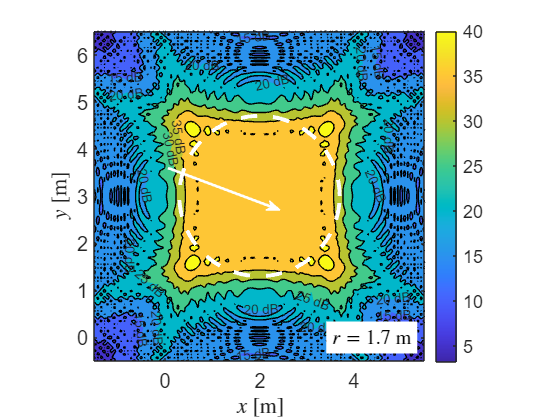

r = 1.7;% radius
q = 0:0.01:2*pi; % angle 0 to 360 degrees in radian
x = r*cos(q)+center(1);    % cartesian x coordinate
y = r*sin(q)+center(2);    % cartesian y coordinate
plot(x,y,'Color','white','LineStyle','--','LineWidth',3)

annotation("arrow",[0.3 0.5],[0.6 0.5],'Color','white','LineWidth',2);
text(3.5,0,strcat('$r=',num2str(r),'$ m'),'Interpreter','latex','FontSize',fontsize,'BackgroundColor','white');

axis square
xlabel('$x$ [m]','Interpreter','latex');
ylabel('$y$ [m]','Interpreter','latex');
set(gca,'FontSize',fontsize);

#### References

[1] WLAN PPDU Structure, [https://www.mathworks.com/help/wlan/gs/wlan-ppdu-structure.html](https://www.mathworks.com/help/wlan/gs/wlan-ppdu-structure.html)